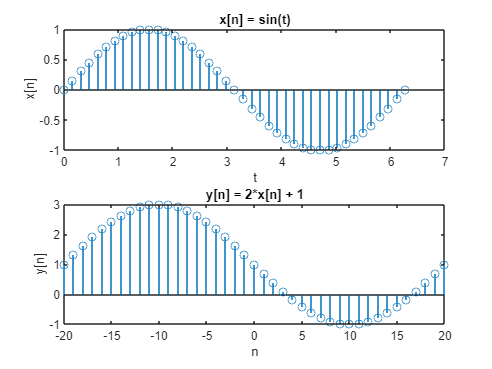

% Given system defined by the equation
% y[n] = 2*x[n] + 1
% x[n] = sin(t)

% Define the range of n
n = -20:20;

% Define the input signal x[n]
t = linspace(0, 2*pi, numel(n));
x = sin(t);

% Define the output signal y[n]
y = 2*x + 1;

% Plot the input signal
subplot(2, 1, 1);
stem(t, x);
title('x[n] = sin(t)');
xlabel('t');
ylabel('x[n]');

% Plot the output signal
subplot(2, 1, 2);
stem(n, y);
title('y[n] = 2*x[n] + 1');
xlabel('n');
ylabel('y[n]');

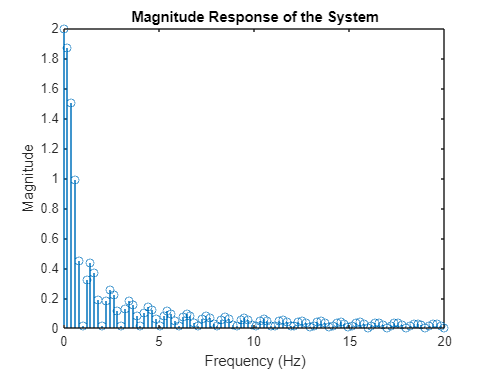


% Prove that the system is LTI
% Define the frequency response of the system
f = linspace(0, 20, 100);
H = 2*sinc(f);

% Plot the magnitude response of the system
figure;
stem(f, abs(H));
title('Magnitude Response of the System');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

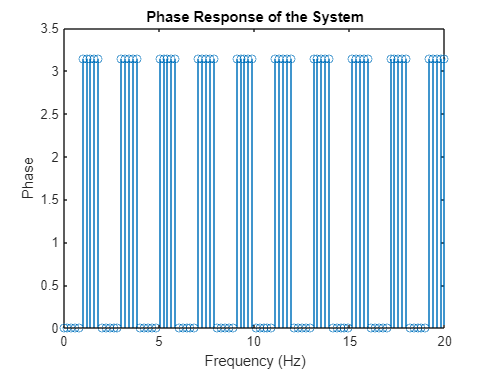


% Plot the phase response of the system
figure;
stem(f, angle(H));
title('Phase Response of the System');
xlabel('Frequency (Hz)');
ylabel('Phase');


% Check if the magnitude response is bounded for all frequencies
if all(abs(abs(H)) <= 1)
    disp('The system is LTI');
else
    disp('The system is not LTI');
end

The system is not LTI
